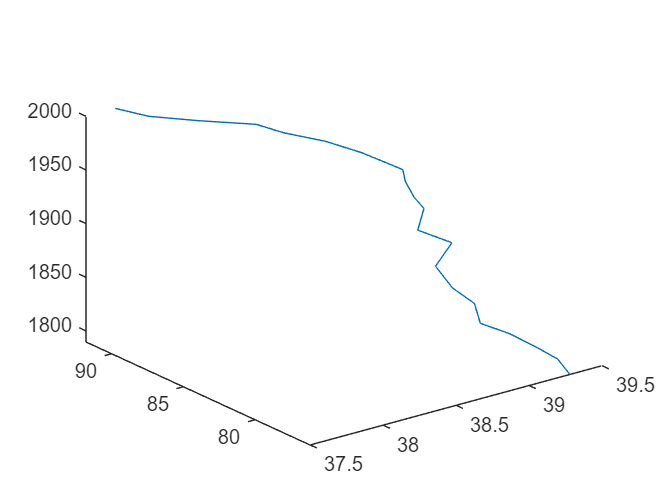

clear;
load popcenter.dat;
decade = popcenter(:,1);
north = popcenter(:,2);
west = popcenter(:,3);
hold off;
plot3(north, west, decade);

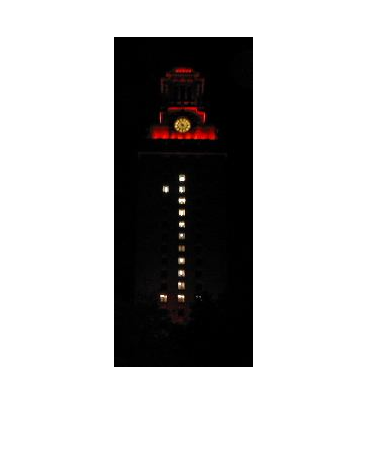

I = imread('tower.jpg'); 
imshow(I);

for m = 1:3 % add contrast for each layer
    J(:,:,m) = histeq(I(:,:,m));
end;

Unrecognized function or variable 'histeq'.

K = [ I J ]; % place old and new side by side
imshow(K) % display the contrast
imwrite(K,'towercontrast.jpg') % write new file

Z = [eye(2) eye(2) eye(2) eye(2)];
Z4 = [Z;Z;Z;Z]

Z4 =      1     0     1     0     1     0     1     0
     0     1     0     1     0     1     0     1
     1     0     1     0     1     0     1     0
     0     1     0     1     0     1     0     1
     1     0     1     0     1     0     1     0
     0     1     0     1     0     1     0     1
     1     0     1     0     1     0     1     0
     0     1     0     1     0     1     0     1


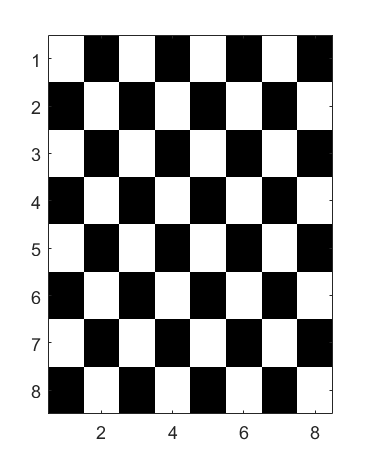

C = 2*ones(8) - Z4;
colors(1,:) = [ 1 1 1 ]; % pointer value 1 white
colors(2,:) = [ 0 0 0 ]; % pointer value 2 black 
image(C)
colormap(colors)